load uspsDigits.mat;

% centroid metoden
%ima(testDigits(:,:,1))

randImgIndex = randi(2007)

randImgIndex = 72

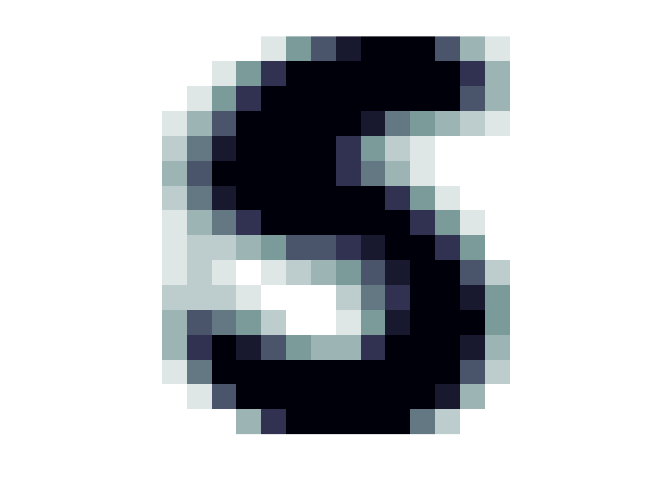


indexFour = find(testAns == 5);

mean(testDigits(indexFour),3);
sumFour = zeros(16,16,1);
for c = 1:length(indexFour)
    indexValue = indexFour(c);
    testDigits(:,:,indexValue);
    sumFour(:,:,1) = sumFour(:,:,1) + testDigits(:,:,indexValue);
end
meanFour = sumFour./length(indexFour);
ima(meanFour)

randImgIndex = randi(2007)

randImgIndex = 847

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;
for c = 1:2007
    if c ~= randImgIndex
        tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
        if tempDiff < savedDiff
            savedDiff = tempDiff;
            savedIndex = c;
        end
    end
end 
savedIndex

savedIndex = 1246

savedDiff

savedDiff = 5.1362e-05

testAns(randImgIndex)

ans = 4

testAns(savedIndex)

ans = 8

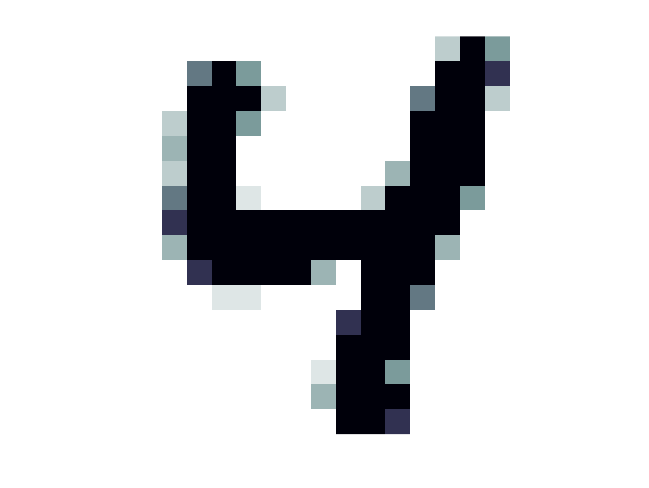

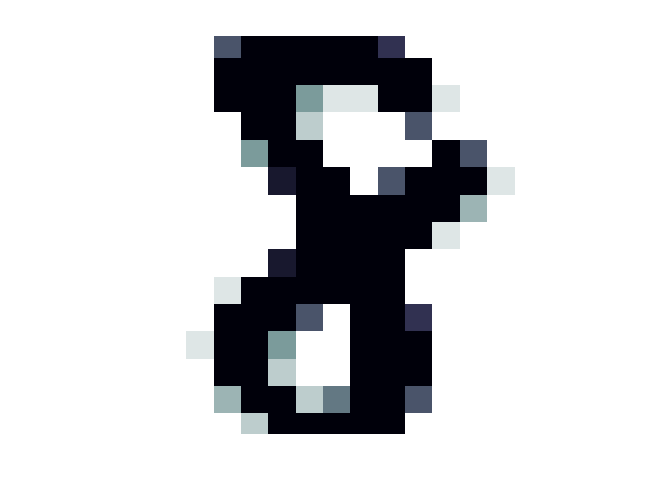

ima(testDigits(:,:,randImgIndex))
ima(testDigits(:,:,savedIndex))

randImgIndex = randi(2007)

randImgIndex = 64

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;

nClosesNeighbooorIndex = [0;0;0;0;0];
nClosesNeighbooorValues = [savedDiff;savedDiff;savedDiff;savedDiff;savedDiff];

for n = 1:5
    for c = 1:2007
        if c ~= randImgIndex && c ~= nClosesNeighbooorIndex(1) && c ~= nClosesNeighbooorIndex(2) && c ~= nClosesNeighbooorIndex(3) && c ~= nClosesNeighbooorIndex(4) && c ~= nClosesNeighbooorIndex(5)
            tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
            if tempDiff < nClosesNeighbooorValues(1)
                nClosesNeighbooorValues(1) = tempDiff;
                nClosesNeighbooorIndex(1) = c;
            elseif tempDiff < nClosesNeighbooorValues(2)
                nClosesNeighbooorValues(2) = tempDiff;
                nClosesNeighbooorIndex(2) = c;
            elseif tempDiff < nClosesNeighbooorValues(3)
                nClosesNeighbooorValues(3) = tempDiff;
                nClosesNeighbooorIndex(3) = c;
            elseif tempDiff < nClosesNeighbooorValues(4)
                nClosesNeighbooorValues(4) = tempDiff;
                nClosesNeighbooorIndex(4) = c;
            elseif tempDiff < nClosesNeighbooorValues(5)
                nClosesNeighbooorValues(5) = tempDiff;
                nClosesNeighbooorIndex(5) = c;
            end
        end
    end 
end



nClosesNeighbooorIndex

nClosesNeighbooorIndex =         1036
        1680
        1532
        1931
         150


testAns(nClosesNeighbooorIndex)

ans =      3
     9
     4
     9
     9


nClosesNeighbooorValues

nClosesNeighbooorValues =     0.0013
    0.0023
    0.0032
    0.0039
    0.0045


testAns(randImgIndex)

ans = 2